# Neural Network Generation 

## House keeping

%%% Data generation for NN
set(0,'ShowHiddenHandles','on'); %delete(get(0,'Children')); % close windows
close all; clear all;

## Code Run Choice 


% Phases to run
use_cached_data = false;         % if false, generate new data
use_cached_net = false;          % if false, generate new NARX net
do_train = true;               % if true, perform training
recover_checkpoint = true;     % if training did not finish, use checkpoint
archive_net = true;            % archive NN, data and figures to subfolder

## Data Generation

generates random voltage steps bwteen +- max voltage


%% Data generation phase
if (use_cached_data==false)
    disp('Generating and caching data...')
    
    time_step = 0.01;
    max_voltage = 10;
    num_entries = 1e5;

    min_time_jump = 5/time_step;
    max_time_jump = 20/time_step;
    i = 5;
    voltage = zeros(i,1,1)'
    while i<num_entries
       voltage_now = rand()*(max_voltage) - (max_voltage/2) ; 
       time_jump = randi(max_time_jump-1) + min_time_jump;
       j = i;
       while j<(i+time_jump)
           voltage(j) = voltage_now;
           j = j + 1;
       end
       i = i + time_jump;
    end
    
    clear i j
    
    voltage = voltage(1:num_entries); % clip off unwanted extra values.
    t = linspace(0,time_step*num_entries,num_entries);
    
    
   % graph of input data that is applied to the black box
    plot(t,voltage)   

## Import Black Box


    % blackbox parameters
    System_parameters;
    
    % simulation
    start_simulink;
    model = 'NeuralNetUnitLDC_IO.slx';
    load_system(model);
    
    input = timeseries(voltage,t,'Name','input to blackbox');
    out_temp = sim(model, 'SrcWorkspace','current',...
            'StartTime',string(t(1)),...
            'StopTime',string(t(end)),...
            'FixedStep', string(time_step));
    output = out_temp.output;

    % prepare the data after simulation
    in_data = num2cell(input.Data(:)');
    target_data = num2cell(output.Data(1:end-1)');
    
    % report sizes:
    fprintf("Data set of %d entries \n", numel(in_data));
    [a,b] = size(in_data);
    fprintf("Data consists of %d timesteps of %d elements\n",b,a);
   
    save('cache/IO_data',...
        'in_data','target_data',...
        'time_step','t', 'model');
    clear v_input voltage_steps out_temp tout v_1 v_2 i input output
    clear time_jump max_voltage num_entries voltage_now max_time_jump
    disp("Data generated")
else
    load('cache/IO_data');
    disp('Loaded IO data from cache...')
end

Generating and caching data...


voltage =      0     0     0     0     0


Data set of 100000 entries 


Data consists of 100000 timesteps of 1 elements


Data generated


## Generation of the NN

%% NARX creation phase
if (use_cached_net==false)
    disp("Creating NARX net...")

    fprintf("NARX net has input size: %d \n", numel(t));
    trained_status = false;

    % NN setup
    input_delays = 1:2;
    feedback_delays = 1:2;
    hidden_layers = 10;
    net = narxnet(input_delays,feedback_delays,hidden_layers);
    net.divideFcn = 'divideblock';
    net.divideParam.trainRatio = 75/100;
    net.divideParam.valRatio = 15/100;
    net.divideParam.testRatio = 10/100;

    save('cache/NN_model',...
        'trained_status','net');
    clear numelements indices indices indices_new indices_main
    disp('Cached untrained NARX net')
else
    load('cache/NN_model');
    if (trained_status)
        disp('Trained NARX net loaded from cache...')
        if (training_complete==false)
            disp("WARNING: training was stopped by user previously")
        end
    else
        disp('Untrained NARX net loaded from cache...')
    end
end

Creating NARX net...


NARX net has input size: 100000 


Cached untrained NARX net



[inputs,feedbackDelays,layerStates,targets] = ...
        preparets(net,in_data,{},target_data);

## Training NN

%% Training phase
if do_train
    disp("Training NARX net (open loop)")
    training_complete = false;
    if (recover_checkpoint==true)
        if exist('cache/checkpoint.mat','file') == 2
            load('cache/checkpoint.mat');
            disp("Recovered last checkpoint")
            [inputs,feedbackDelays,layerStates,targets] = ...
                preparets(net,in_data,{},target_data);
        else
            disp("Unable to recover last checkpoint, retraining")
        end
    end
    
    net.trainFcn =  'trainlm';
    net.trainParam.epochs = 1000;
    net.trainParam.show = 10;
    net.trainParam.min_grad = 1e-10;
    net.trainParam.max_fail = 10;
    [net,TR] = train(net,inputs,targets,feedbackDelays,...
        'CheckpointFile','cache/checkpoint.mat');
    beep;
    disp("Training complete")
    trained_status = true;
    if strcmp(TR.stop,"User stop.")==false
        training_complete = true;
    end
    if exist('cache/checkpoint.mat','file') == 2
        delete cache/checkpoint.mat;
    end
    
    save('cache/NN_model','inputs','feedbackDelays','layerStates','targets',...
        'in_data','target_data','TR',...
        'trained_status','training_complete','net');
    disp('Cached trained NARX net')
end

Training NARX net (open loop)


Unable to recover last checkpoint, retraining


02-Apr-2019 16:39:12 First Checkpoint #1: cache\checkpoint.mat


02-Apr-2019 16:40:28 Write Checkpoint #2: cache\checkpoint.mat
02-Apr-2019 16:41:28 Write Checkpoint #3: cache\checkpoint.mat
02-Apr-2019 16:42:29 Write Checkpoint #4: cache\checkpoint.mat
02-Apr-2019 16:43:29 Write Checkpoint #5: cache\checkpoint.mat
02-Apr-2019 16:44:29 Write Checkpoint #6: cache\checkpoint.mat
02-Apr-2019 16:44:52 Final Checkpoint #7: cache\checkpoint.mat


Training complete


Cached trained NARX net


## Performance Test and Plots

performance_open = 7.7488e-06

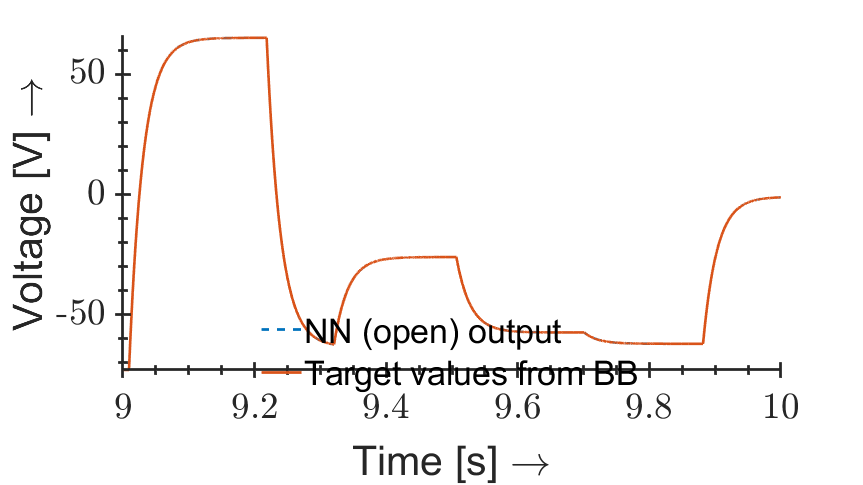

Undefined function or variable 'FillAxesPos'.

Error in plot_outputOpen (line 84)
axOutputOpen.Position = FillAxesPos(axOutputOpen,0.99);

%% Training tests and performance evaluation

if trained_status
    % simulate the network and plot the resulting errors
    outputs = sim(net,inputs,feedbackDelays);
    errors = gsubtract(targets,outputs);
    performance_open = perform(net,targets,outputs)

    % figures
    plot_outputOpen;
    plot_errorOpen;


    %% Deployment and testing

    % Close the loop
    net_closed = closeloop(net);

    % Test the NARX net with original data
    [inputs_c,feedbackDelays_c,layerStates_c,targets_c] = ...
        preparets(net_closed,in_data,{},target_data);
    outputs_closed  = net_closed(inputs_c,{},layerStates_c);
    % outputs_closed_sim  = sim(net_closed,inputs_c,{});
    errors_closed = gsubtract(targets_c,outputs_closed);
    performance_closed = perform(net_closed,targets_c,outputs_closed)

    % figures
    
    plot_trainPerform;
    plot_trainState;
    plot_trainRegression;
    
    plot_outputClosed;
    plot_errorClosed;
    pause(4)

    plot_netView;
    
    clear max_val max_index 

end


%% Save metadata, caches and matlab script
if (archive_net) && (trained_status)
   disp('Copying data, please wait...')
   currentFileName = 'NN_Modelling_v04.m';
   if (exist(currentFileName)==2)
       foldername = mlreportgen.utils.hash(string(datetime('now')));
       foldername = strcat("cache/", extractBefore(foldername,8));
       mkdir(foldername);
       copyfile(currentFileName, foldername);
       copyfile('cache/NN_model.mat',foldername);
       copyfile('cache/IO_data.mat',foldername);
       figHandles = findobj('Type', 'figure');
       for i=1:length(figHandles)
            figure(figHandles(i).Number);
            fig_name = figHandles(i).Name;
            fig_name(isspace(fig_name)==1)='_';
            fig_name = regexprep(fig_name, '[ .,''!?()]', '');
            fn = sprintf('%s/%s.eps',foldername,fig_name);
            export_fig(fn,figHandles(i))
       end
       gensim(net_closed,time_step);
       fn = sprintf('%s/narx.slx',foldername);
       save_system(gcs,fn)
       bdclose(gcs);
       pause(6);
       close all;
       fprintf("Data archived in %s\n",foldername)
   else
       dprintf('WARNING: %s does not exist!\n',currentFileName);
   end
else
    disp("WARNING: output NARX data not archived")
end